# Derivation of Quadrotor State Equations

To design the controller, the state-space equations first need to be derived. For the derivation, the following coordinate systems and motor numerations are assumed. Note that the z-axis is pointing downwards.

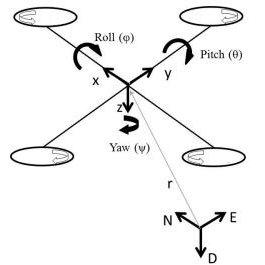

The Symbolic Toolbox is a perfect tool to derive the state equations and save them as MATLAB Functions. First, let's declare the symbolic variables for states, inputs (MVs) and parameters.

%Clear the variables from the workspace
clear;
clc;
%% Create symbolix variables for states, inputs, MVs and parameters
syms F_ext_x F_ext_y F_ext_z
syms k m g omegaMax2
syms x y z  u v w 
syms phi theta psi T

where:

**States **

$x$: x position in global coordinates [m]

$y$: y position in global coordinates [m]

$z$: z position in global coordinates [m]

$u$: x velocity in global coordinates [m/s]

$v$: y velocity  in global coordinates [m/s]

$w$: z velocity  in global coordinates [m/s]

**Control Inputs**

$\phi$ (phi): roll angle [rad]

$\theta$ (theta): pitch angle [rad]

$\psi$ (psi): yaw angle [rad]

*T*: Normalized Collective Thrust of 4 rotors

**Parameters**

$g$: gravitational acceleration [m/s^2]

$k$: rotor lift constant [kg*m]

## Set values for dynamics parameters


kVal = 1.01e-6;  %Units N * s^2 = kg * m
mVal = 1;  %Units kg
omegaMax2Val = 7.79e6;  %Units (rad / s)^2
gVal = 9.81; %Units kg * m / s^2
UAVparamValues = [kVal mVal gVal omegaMax2Val];

During the flight, the quadcopter's coordinated system will be rotating. Therefore, we need to relate body-fixed coordinates to the inertial coordinates using  a rotational matrix.

% R- ZYX Euler
Rz = [cos(psi), -sin(psi), 0;
      sin(psi), cos(psi) , 0;
      0       , 0        , 1]

$$Rz = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ry = [cos(theta) , 0, sin(theta);
      0          , 1, 0         ;
      -sin(theta), 0, cos(theta)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Rx = [1, 0, 0;
      0, cos(phi), -sin(phi);
      0, sin(phi), cos(phi)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$


% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx

$$R\_Euler = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

The thrust generated by the rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Recall that the input for propeller $i$ is $\omega^2_i/\omega_{max}^2\in[0,1]$. Therefore, the total thrust generated is 

% Collective Thrust force T in [0,1]
Fz = -k * T * 4 * omegaMax2

$$Fz = -4\,T\,k\,{\mathrm{omegaMax}}_{2}$$

The produced thrust also generates moments around the x and y-axis:


$$L_i=\pm l \cdot F_{z_i} = \pm l \cdot k \cdot \omega^2_i$$



$$M_i=\pm l \cdot F_{z_i} = \pm l \cdot k \cdot \omega^2_i$$


where $L$ and $M$ are moments acting on the x and y-axis respectively and $l$ is the moment arm of the thrust. Due to symmetry of the drone the $l$ value is the same for both axis.

Additionaly, the drag created at the blades needs to be counteracted by motor torque:


$$N_i = \frac{\pm R \cdot Drag}{2} = \pm \frac{R}{4} \rho c_D V_{tip,i}^2 \cdot A_{ref}= \pm \frac{1}{4} \rho c_D R^3 \cdot A_{ref} \cdot \omega_i^2 = \pm b \cdot \omega^2_i$$


where $c_D$ is the drag coefficient related to the blade geometry. Similarly as with the thrust, all variables except $\omega^2$ are constant and substituted with a single parameter $b$. Therefore, the total acting moments are:

Note the positive moments are defined by the right-hand rule. Having defined the acting forces and rotational matrix, we can start deriving equations of motion. Firstly, the rate of change of the global frame positions is simply the velocity vector in the global frame of reference:

% Position in global frame of reference
f(1:3) = [u; v; w];

The linear acceleration of the system is obtained from Newton's Second Law, with the thrust vector rotated to the inertial frame:

% Acceleration in inertial frame
% Note that external force(wind) is added
f(4:6) = R_Euler*[0;0;Fz]/m + [0;0;g] + [F_ext_x; F_ext_y; F_ext_z]/m; 

Use MATLAB [subs](https://www.mathworks.com/help/symbolic/subs.html) function to replace the parameters variables with their values and [simplify](https://www.mathworks.com/help/symbolic/simplify.html) the result:

% Replace parameters
% f = subs(f, [k m g omegaMax2], paramValues);
f = subs(f, psi ,0);
f = simplify(f);    
disp([f(1);f(2);f(3);f(4);f(5);f(6)] );

$$\left(\begin{array}{c} u\\ v\\ w\\ \frac{F_{\mathrm{ext},x}-4\,T\,k\,{\mathrm{omegaMax}}_{2}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{m}\\ \frac{F_{\mathrm{ext},y}+4\,T\,k\,{\mathrm{omegaMax}}_{2}\,\sin\left(\varphi \right)}{m}\\ \frac{F_{\mathrm{ext},z}+g\,m-4\,T\,k\,{\mathrm{omegaMax}}_{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}\right)$$

% Group symbolic variables
state = [x y z u v w ];
control = [phi theta T];
wind = [F_ext_x F_ext_y F_ext_z];
UAVPara = [ k m g omegaMax2];
% calculate the u_eq
T_eq = (mVal*gVal)/(4*kVal*omegaMax2Val);
u_eq = [0 0 T_eq]'

u_eq =          0
         0
    0.3117


% RK4
syms h
k1 = f;
k2 = subs(f, state, state + 0.5*h*k1);
k3 = subs(f, state, state + 0.5*h*k2);
k4 = subs(f, state, state + h*k3);
x_next = state + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
hVal = 0.05;                       % Integration step size
x_next = subs(x_next,h,hVal);
x_next = subs(x_next,UAVPara,UAVparamValues);
x_next = subs(x_next,wind,[0 0 0]);
x_next = simplify(x_next);

disp([x_next(1);x_next(2);x_next(3);x_next(4);x_next(5);x_next(6)] );

$$\left(\begin{array}{c} \frac{u}{20}+x-\frac{46443884063212605225\,T\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{1180591620717411303424}\\ \frac{v}{20}+y+\frac{46443884063212605225\,T\,\sin\left(\varphi \right)}{1180591620717411303424}\\ \frac{w}{20}+z-\frac{46443884063212605225\,T\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{1180591620717411303424}+\frac{981}{80000}\\ u-\frac{232219420316063026125\,T\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{147573952589676412928}\\ v+\frac{232219420316063026125\,T\,\sin\left(\varphi \right)}{147573952589676412928}\\ w-\frac{232219420316063026125\,T\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{147573952589676412928}+\frac{981}{2000} \end{array}\right)$$

Having defined the state equations, obtain their Jacobians using [jacobian](https://www.mathworks.com/help/symbolic/sym.jacobian.html)

% Calculate Continuous linearized system
A = jacobian(x_next,state);
B = jacobian(x_next,control);

disp(A);

$$\left(\begin{array}{cccccc} 1 & 0 & 0 & \frac{1}{20} & 0 & 0\\ 0 & 1 & 0 & 0 & \frac{1}{20} & 0\\ 0 & 0 & 1 & 0 & 0 & \frac{1}{20}\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$


disp(B);

$$\left(\begin{array}{ccc} \frac{46443884063212605225\,T\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{1180591620717411303424} & -\frac{46443884063212605225\,T\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{1180591620717411303424} & -\frac{46443884063212605225\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{1180591620717411303424}\\ \frac{46443884063212605225\,T\,\cos\left(\varphi \right)}{1180591620717411303424} & 0 & \frac{46443884063212605225\,\sin\left(\varphi \right)}{1180591620717411303424}\\ \frac{46443884063212605225\,T\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{1180591620717411303424} & \frac{46443884063212605225\,T\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{1180591620717411303424} & -\frac{46443884063212605225\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{1180591620717411303424}\\ \frac{232219420316063026125\,T\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{147573952589676412928} & -\frac{232219420316063026125\,T\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{147573952589676412928} & -\frac{232219420316063026125\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{147573952589676412928}\\ \frac{232219420316063026125\,T\,\cos\left(\varphi \right)}{147573952589676412928} & 0 & \frac{232219420316063026125\,\sin\left(\varphi \right)}{147573952589676412928}\\ \frac{232219420316063026125\,T\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{147573952589676412928} & \frac{232219420316063026125\,T\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{147573952589676412928} & -\frac{232219420316063026125\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{147573952589676412928} \end{array}\right)$$

Obviously F_ext is addtive noise and dosen't change the jacobian of the UAV.

% B = subs(B,UAVPara,UAVparamValues);
B = subs(B,control,u_eq');
B = subs(B,psi,0);
double(B);
disp(B);

$$\left(\begin{array}{ccc} 0 & -\frac{1462177479653772969375}{119239753692458541645824} & 0\\ \frac{1462177479653772969375}{119239753692458541645824} & 0 & 0\\ 0 & 0 & -\frac{46443884063212605225}{1180591620717411303424}\\ 0 & -\frac{7310887398268864846875}{14904969211557317705728} & 0\\ \frac{7310887398268864846875}{14904969211557317705728} & 0 & 0\\ 0 & 0 & -\frac{232219420316063026125}{147573952589676412928} \end{array}\right)$$


A = double(A);
B = double(B);
%% Create appropriate files
%% Create QuadrotorStateFcn.m
% matlabFunction(transpose(f),'File','WindNoiseQuadrotorStateFcnBase',...
% 'Vars',{transpose(state),transpose(control),wind,UAVPara});


Having defined state equations, we can also find the motor speeds required to achieve equilibrium at given coordinates. 

To maintain stable position and orientation, all velocities need to be zero. This also means the pitch and yaw angle need to be zero as well.

Finally, look at the state equations and answer the following question: Does the position of the drone affect equilibrium? What would be the most convenient point to linearise at?

As an extorquee, one can compute the equilibrium input when the states are all zero using MATLAB functions [subs](https://www.mathworks.com/help/symbolic/subs.html) and [solve](https://www.mathworks.com/help/symbolic/solve.html):    